# Network training workflow

This script loads data from a HDF5 file. The data is normalised and randomised before feed into an Artificial Network for training. The trained weights are output to a text file for use within a LS-Dyna user material. The workspace is cleared and some variables are set. TrainNN defines if the network is trained or a pretrained model is loaded (filename is netname).

clear; close all;clc;
trainNN = 0;
savename='NN_SE_SEcycl_SEma_20_20'; netname=[savename,'_trainedNN.mat'];

The following section is only executed when a new model is trained (trainNN=1)

if trainNN

## Import data from HDF5 file

The file specified in hdf5name is opened and information regarding its content stored in the info variable. Specific content is the loaded into the alldata array.

% load from HDF5
hdf5name = 'TrainingData.hdf5';
info = h5info(hdf5name);
alldata = zeros(4,1);

input = h5read(hdf5name,'/SE/monotonous/SR100/input');
output = h5read(hdf5name,'/SE/monotonous/SR100/output');
ldata = [input; output];
alldata = [alldata ldata]; clear ldata input output;
input = h5read(hdf5name,'/SE/monotonous/SR200/input');
output = h5read(hdf5name,'/SE/monotonous/SR200/output');
ldata = [input; output];
alldata = [alldata ldata]; clear ldata input output;
input = h5read(hdf5name,'/SE/monotonous/SR500/input');
output = h5read(hdf5name,'/SE/monotonous/SR500/output');
ldata = [input; output];

alldata = [alldata ldata]; clear ldata input output;
input = h5read(hdf5name,'/SE/cyclic/normal/input');
output = h5read(hdf5name,'/SE/cyclic/normal/output');
ldata = [input; output];
alldata = [alldata ldata]; clear ldata input output;
input = h5read(hdf5name,'/SE/cyclic/shear_sr100/input');
output = h5read(hdf5name,'/SE/cyclic/shear_sr100/output');
ldata = [input; output];
alldata = [alldata ldata]; clear ldata input output;
input = h5read(hdf5name,'/SE/cyclic/shear_sr200/input');
output = h5read(hdf5name,'/SE/cyclic/shear_sr200/output');
ldata = [input; output];
alldata = [alldata ldata]; clear ldata input output;
input = h5read(hdf5name,'/SE/cyclic/shear_sr500/input');
output = h5read(hdf5name,'/SE/cyclic/shear_sr500/output');
ldata = [input; output];
alldata = [alldata ldata]; clear ldata input output;

input = h5read(hdf5name,'/SE/multiaxial/input');
output = h5read(hdf5name,'/SE/multiaxial/output');
ldata = [input; output];
alldata = [alldata ldata]; clear ldata input output;

alldata(:,1) = [];

The loaded data contains the following variables


% HDF5 data
% 1 previous plastic strain 
% 2 previous eff stress 
% 3 eff_strain_increment
% 4 eps_plast 


Previous plastic strain (network input)

plot(alldata(1,:));
title('Previous plastic strain (network input)');

Previous effective stress (network input)

plot(alldata(2,:));
title('Previous effective stress (network input)');

Effective strain increment (network input)

plot(alldata(3,:));
title('Effective strain increment (network input)');

Effective plastic strain (network output)

plot(alldata(4,:));
title('Effective plastic strain (network output)');

end

## Data preparation

The following section is only executed when a new model is trained (trainNN=1)

if trainNN

The data is randomised and normalised. The values used for normalisation will later be output together with the network weights to enable the reverse process.

% randomly select data
msize = size(alldata);
k = randperm(msize(2));
datared = alldata(:,k(1:msize(2)));
input = datared([1 2 3],:);  % previous plastic strain, previous eff stress, effective strain increment
output = datared(4,:);    % current plastic strain
clear k;

% normalise data
inputreg = max(abs(input'));
input = input./inputreg';
outputreg = max(abs(output'));
output = output./outputreg';

Previous plastic strain (network input normalised)

plot(input(1,:));
title('Previous plastic strain (network input normalised)');

Previous effective stress (network input normalised)

plot(input(2,:));
title('Previous effective stress (network input normalised)');

Effective strain increment (network input normalised)

plot(input(3,:));
title('Effective strain increment (network input normalised)');

Effective plastic strain (network output normalised)

plot(output(1,:));
end

## Network training

This section of the script can be very slow when training is performed on large data sets (many hours, days). Firstly, Matlab live scripts run much slower than standard m scripts (especially in Matlab versions older than 2019). Consider to convert the live script into an m file and then run it for large training sets. In addition, running it on a machine with multiple CPU's also speeds up the process. The Matlab neural network training tool supports parallel processing (this feature is also enables in this example).

Please note that a separate user interface will open during the network training. Training progress can be monitored through that UI. Training can be stopped when the performance plot (open by clicking on Performance button) does not show further improvement.

if trainNN   

Create network (2 hidden layers with 20 units each)

    annstruct = [ 20 20 ];
    

Set training parameters

- trainFcn: optimisation algorithm to use (trainbr has demonstrated fastest convergence and highest accuracy for this dataset)

- epochs: number of iterations during training

- trainRatio: % of data to be used for training (default is 0.7)

- testRatio: % of data to be used for testing the network (default is 0.15)

- valRatio: % of data to be used for validating the network (default is 0.15)

- lr: Learning rate (default 0.001)

- processFcns: define what operations should be performed on the data before training, we alter the defaults as we do our own normalisation

This example uses Tansig activation functions for the hidden layers and a linear activation for the output layer. This is a typical setting for regression problems. The actiivation functions can be changed by setting net1.layers{i}.transferFcn to the required value. Please see Matlab documentation for details.

Note that the parameters discussed here are not complete. There are much more settings to control the network.

    net=feedforwardnet(annstruct);
%     net.trainFcn = 'traingd'; % Gradient descent
    net.trainFcn = 'trainbr'; % Bayesian regularisation
    % net.trainFcn = 'trainlm'; %  Levenberg-Marquardt optimization.
    % net.trainFcn = 'trainscg'; %  Scaled Conjugate Gradient.
    %net.layers{1}.transferFcn = 'poslin';
    %net.layers{2}.transferFcn = 'poslin';
    net.trainParam.epochs = 1000;
    net.divideParam.trainRatio=0.8;
    net.divideParam.testRatio=0.01;
    net.divideParam.valRatio=0.01;
    %net.divideFcn
    % net.trainParam.lr=0.001;
    % net.trainParam.min_grad=1e-20;
    % net.trainParam.goal=1e-30;
    % net = configure(net,input,output);
   
    % switch off pre and post processing
    net.inputs{1,1}.processFcns={'removeconstantrows'};
    net.outputs{1,length(annstruct)+1}.processFcns={'removeconstantrows'};
    % net.trainParam;
    

Initialise training and save trained model

    % [net,tr] = train(net,input,output,'useParallel','yes','useGPU','yes');
    [net,tr] = train(net,input,output,'useParallel','yes');
    save(netname,'input','inputreg','net','output','outputreg','tr');    

If model is loaded

else
    load(netname);
end

## Plot model performance

The learning process is visualised

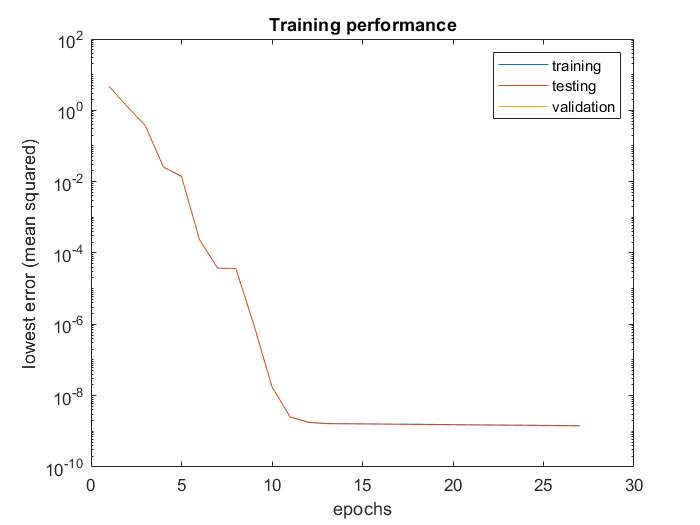

figure
plot(tr.perf);hold on;
plot(tr.tperf);
plot(tr.vperf);
legend('training','testing','validation');
set(gca,'YScale','log');
xlabel('epochs');
ylabel('lowest error (mean squared)');
title('Training performance');

The model is evaluated for the input data used for training and a histogram of errors between training labels and predicted outputs is plotted.

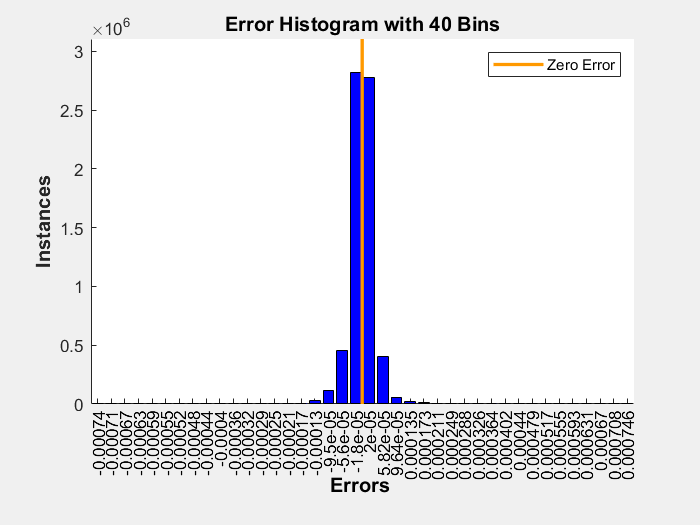

% plot detailled error from final training
outerr = net(input);
lasterr = output-outerr;
nob = 40; % number of bins
figure
ploterrhist(lasterr,'bins',nob);
trresults = outerr.*outputreg'; % reverse normalisation

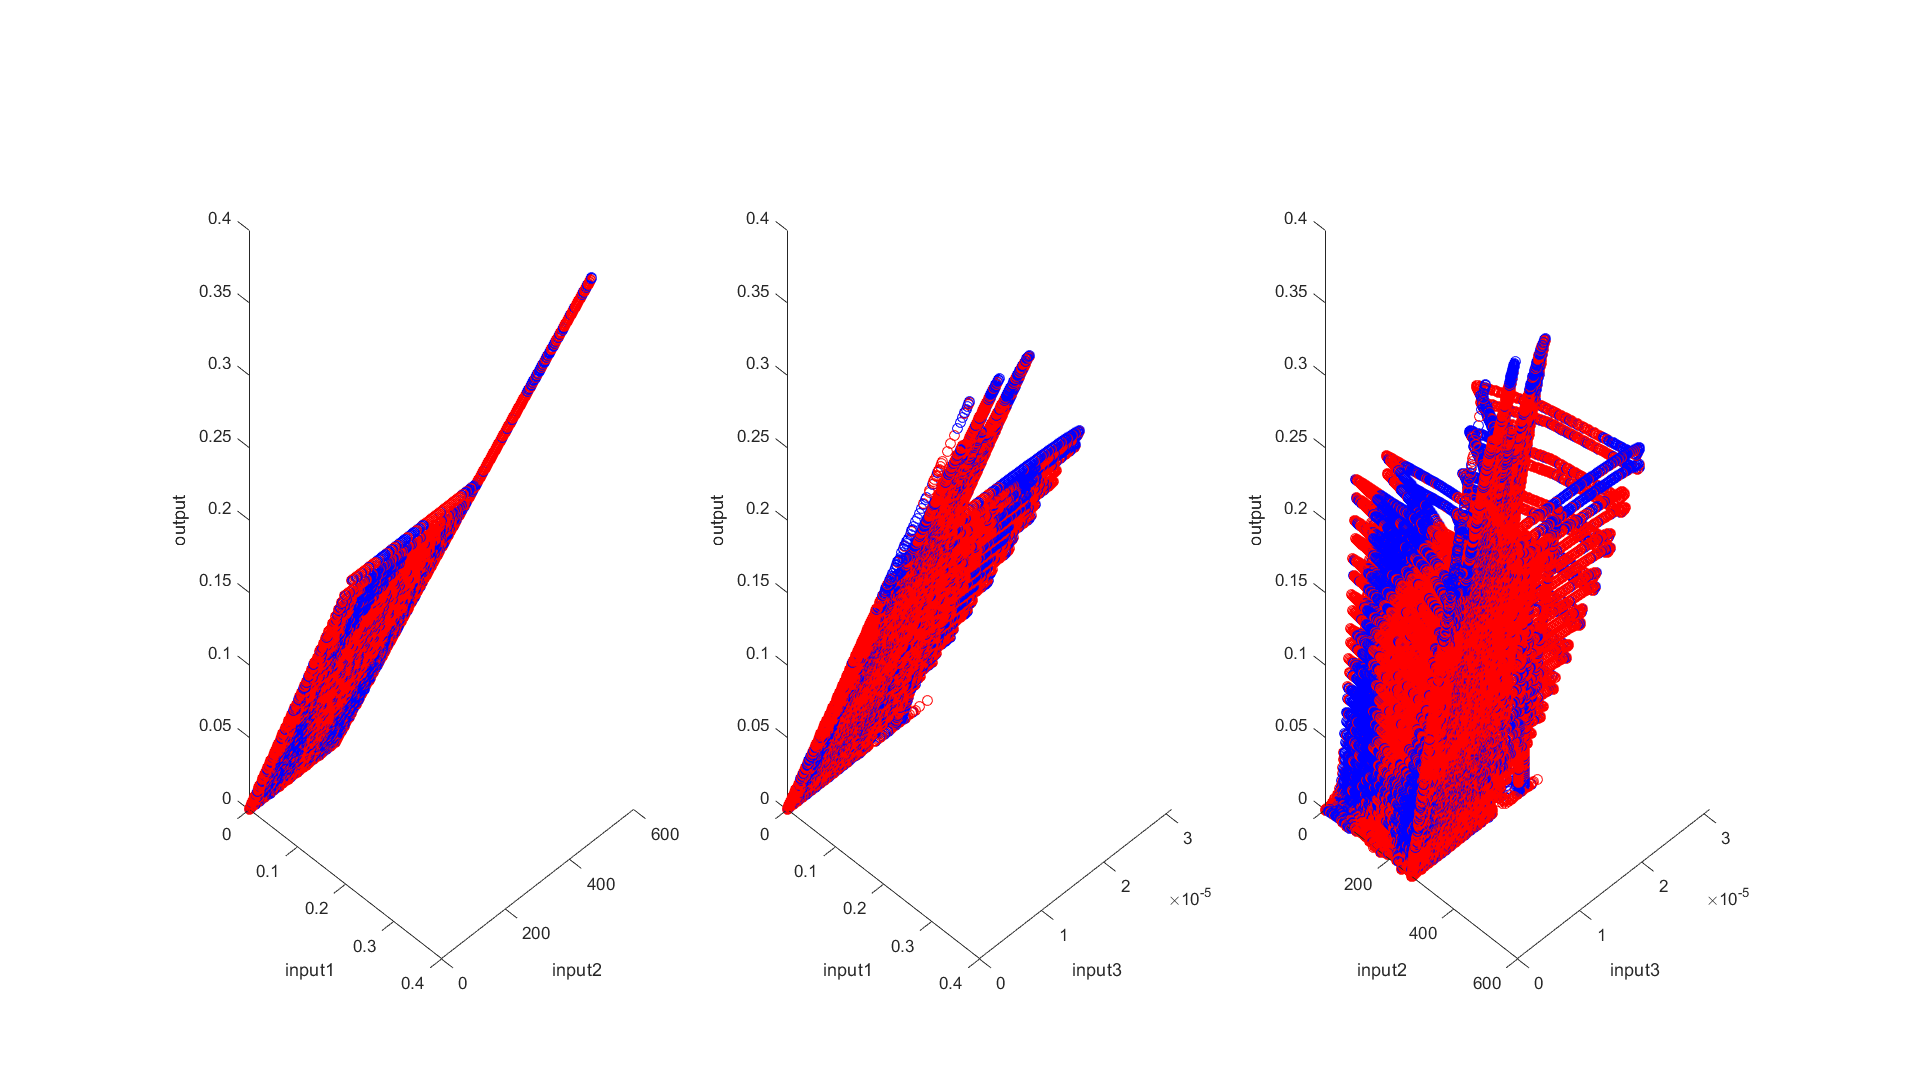

pinput = input.*inputreg'; % reverse normalisation
poutput = output.*outputreg';
% HDF5 input    
figure('units','normalized','outerposition',[0 0 1 1]); % make full screen
sp(1) = subplot(1,3,1);hold all;
plot3(pinput(1,:),pinput(2,:),poutput(1,:),'bo');hold on;
plot3(pinput(1,:),pinput(2,:),trresults(1,:),'ro');hold on;
view(45,20);
sp(2) = subplot(1,3,2);hold all;
plot3(pinput(1,:),pinput(3,:),poutput(1,:),'bo');hold on;
plot3(pinput(1,:),pinput(3,:),trresults(1,:),'ro');hold on;
view(45,20);
sp(3) = subplot(1,3,3);hold all;
plot3(pinput(2,:),pinput(3,:),poutput(1,:),'bo');hold on;
plot3(pinput(2,:),pinput(3,:),trresults(1,:),'ro');hold on;
view(45,20);
xlabel(sp(1),'input1');
ylabel(sp(1),'input2');
zlabel(sp(1),'output');
xlabel(sp(2),'input1');
ylabel(sp(2),'input3');
zlabel(sp(2),'output');
xlabel(sp(3),'input2');
ylabel(sp(3),'input3');
zlabel(sp(3),'output');

## Output weights of the model

The trained weights are extracted from the trained model (stored in net). 

% some NN properties
layers=net.layers;
% extract weights
Iweights = net.IW;
Lweights = net.LW;
bias = net.b;
weights{1}(:,1) = bias{1,1};
weights{1}(:,2:4) = Iweights{1,1};
for i=2:size(layers,1)
    weights{i}(:,1) = bias{i,1};
    ns = size(Lweights{i,i-1},2);
    weights{i}(:,2:ns+1) = Lweights{i,i-1};
end

The weights are output to file formated for direct inclusion into a fortran constitutive model for LS-Dyna.

fid=fopen('weights.txt','w');
fprintf(fid,['c Network: ',savename,'\n']);
fprintf(fid,'c data normalisation\n');
fprintf(fid,'c max of absolute approach\n');
for i=1:length(inputreg)
    fprintf(fid,['      inputreg(',num2str(i),') = %25.20f\n'],inputreg(i));
end
for i=1:length(outputreg)
    fprintf(fid,['      outputreg(',num2str(i),') = %25.20f\n'],outputreg(i));
end
fprintf(fid,'c weights of Neural Network\n');
for i=1:size(weights,2)
    for k=1:size(weights{1,i},1)
        for m=1:size(weights{1,i},2)
            fprintf(fid,['      weights(',num2str(i),',',num2str(k),',',num2str(m),') = %25.20f\n'],weights{1,i}(k,m));
        end
    end
end
fclose(fid);